# forward back model

%L1 = Link ([0 l1 0 pi/2],'standard');
%L1.isrevolute
%L1.qlim =  pi/180*[-180 18

%[theta d a alpha sigma offset]
%theta [rad] angle of joint
%d length of prismatic componet
%a length of link
%alpha [rad] link twist angle
%sigma == 1 is prismatic  == 0 is revolute
%offset
link1 = Link( [ deg2rad(0), 0, 22.75+8.517, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [-2 2];

link2 = Link( [           0, 0,     0, 0, 1, 0], 'standard' );
link2.qlim = [0 12];

modelMasterY = SerialLink( [link1, link2], 'name', 'masterY')

 
modelMasterY = 
 
masterY:: 2 axis, RP, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|     31.267|          0|          0|
|  2|          0|         q2|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


link1 = Link( [ deg2rad(0), 0, 22.75, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [-2 2];

link2 = Link( [           0, 0,     0, 0, 1, 0], 'standard' );
link2.qlim = [0 12];
%39.486
link3 = Link( [ deg2rad( 43.73+90), 0, 29.16, 0, 0, 0], 'standard' );
link3.qlim = pi/180 * [ 43.73+90 43.73+90];

link4 = Link( [ deg2rad(-90-39.486), 0, 22.75, 0, 0, 0], 'standard' );
link4.qlim = pi/180 * [-90-39.486-5 -90-39.486+5];

link5 = Link( [           0, 0,     0, 0, 1, 0], 'standard' );
link5.qlim = [0 12];

modelSlaveY = SerialLink( [ link1, link2, link3, link4, link5 ], 'name', 'slaveY' )

 
modelSlaveY = 
 
slaveY:: 5 axis, RPRRP, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|      22.75|          0|          0|
|  2|          0|         q2|          0|          0|          0|
|  3|         q3|          0|      29.16|          0|          0|
|  4|         q4|          0|      22.75|          0|          0|
|  5|          0|         q5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%inputs forward kinematics
spottingFWDCylinderExtension = 6 %limit is 0 to 12

spottingFWDCylinderExtension = 6

patternFWDCylinderExtension = 6 %limit is 0 to 12

patternFWDCylinderExtension = 6

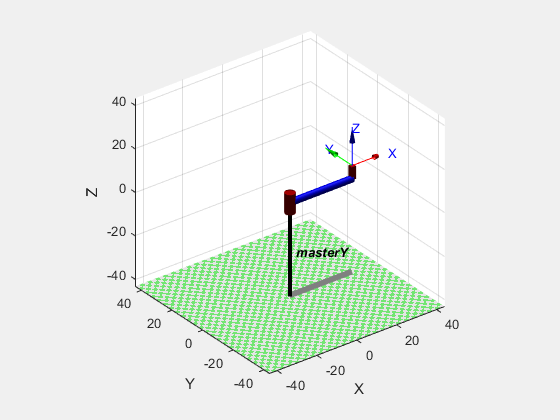

Tmaster = [deg2rad(0), spottingFWDCylinderExtension ];
Tslave = [ deg2rad( 0 ), spottingFWDCylinderExtension, deg2rad(90+39.486), deg2rad( -90-39.486 ), patternFWDCylinderExtension];
%remember to add hammer distance of 8.517
modelMasterY.plot(Tmaster)

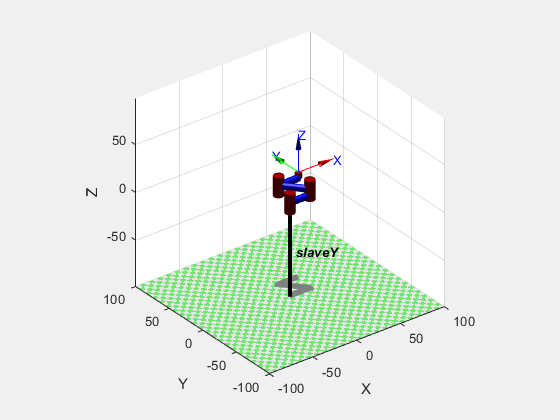

modelSlaveY.plot(Tslave)

hammerDistance = 8.517;

%input inverse kinematic
masterHoleY = 37.266

masterHoleY = 37.2660

slaveHoleY = 37.344

slaveHoleY = 37.3440

spottingFWDCylinderExtension = masterHoleY - link1.a - hammerDistance

spottingFWDCylinderExtension = 5.9990

link2.d = spottingFWDCylinderExtension;
patternFWDCylinderExtension = slaveHoleY - link4.a + (link3.a * sin( link3.theta) ) - link1.a - link2.d

patternFWDCylinderExtension = 6.9162

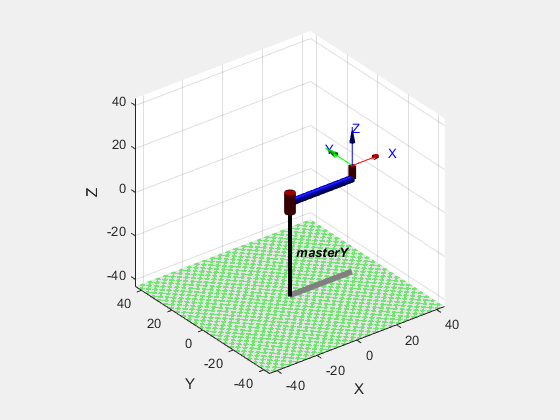

Tmaster = [deg2rad(0), spottingFWDCylinderExtension ];
Tslave = [ deg2rad( 0 ), spottingFWDCylinderExtension, deg2rad(90+39.486), deg2rad( -90-39.486 ), patternFWDCylinderExtension];
modelMasterY.plot(Tmaster)

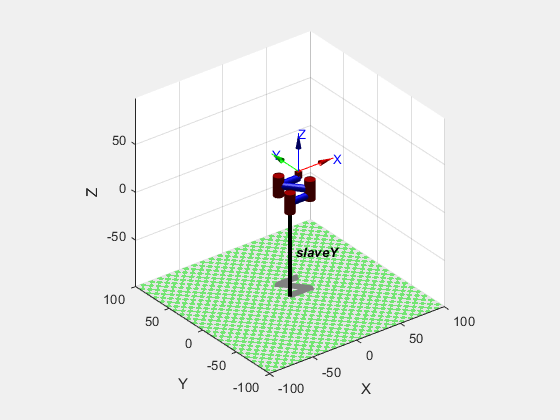

modelSlaveY.plot(Tslave)